# Split-bergman inpainting

split-bergman inpainting using  gauss-seidel without SOR and using neuman boundary condition

**note:** by matlab specification this file [live script] only work on matlab 2016a or above

## section1: intial test image

% clear all previous run variable and windows
clc;clear;close all;

then we intial image from create_inpaintbar (result show below)

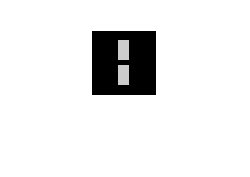

%create image
[image,inpaint_domain] =  CreateInpaintBar(64,64,20,10,2);
imshow(image)

then change it range from [0-255] to [0-1] and create original image for measurement PSNR and RMSE

original_image = double(image+inpaint_domain)/255;
inpaint_domain = inpaint_domain < 1;
image = double(image)/255;
inpaint_domain = double(inpaint_domain);

## section2: testing

define variable for testing (see [publication: Total Variation Inpainting using Split Bregman](http://www.ipol.im/pub/art/2012/g-tvi/) )

lambda = 100;
theta = 1/10000; % in publication use little gamma insted
tolerant = 1e-6;
max_iteration = 1000; % force stop compute if iteration exceed to prevent forever loop

%merge lambda with inpaint domain
lambda = lambda * inpaint_domain;

inpainting

tic;
inpainted_splitbergman_image = SplitBergmanInpainter(image,lambda,theta,tolerant,max_iteration);

processed with 3 loops

toc %processed time measurement

Elapsed time is 0.061160 seconds.


calculating PSNR and RMSE

disp('RMSE ')

RMSE 


disp(sqrt(mean((inpainted_splitbergman_image(:) - original_image(:)).^2))); 

    0.0927



disp('PSNR')

PSNR


disp(psnr(inpainted_splitbergman_image,original_image))

   20.6582



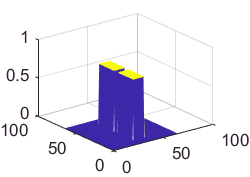

mesh(inpainted_splitbergman_image)